## 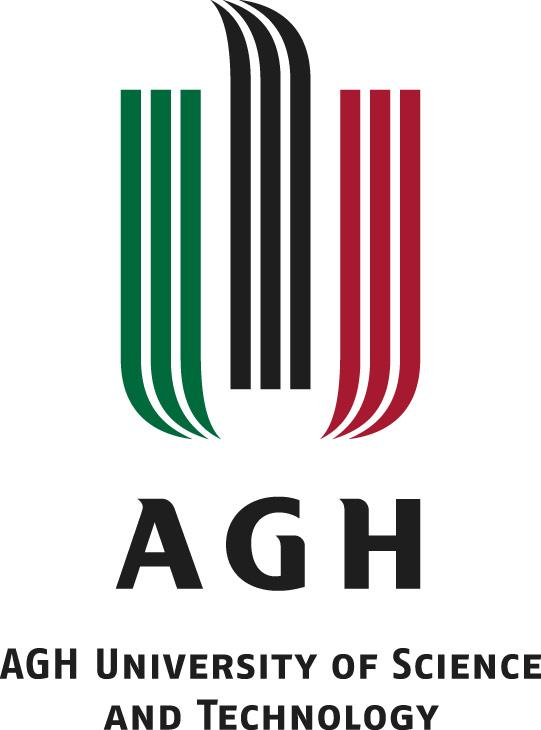

# MECHATRONIC DESIGN

# Lab 2: Introduction to Finite Element (FE) method using CALFEM toolbox (static analysis)

## Mikołaj Suchoń

## Task 1

clear
% ------ Define Topology matrix
% Edof = [ele1, dof1, dof2
% ele2, dof1, dof2
% ..., ..., ...]
Edof = [1 1 2
 2 2 3
 3 2 3];
k = 1500; % N/m
F = 100; % N
% ------ Initiate stiffness matrix K and load vector f
K = zeros(3, 3);
f = zeros(3, 1);
f(2) = F;
% ------ Generate stiffness element matrix
ep1 = k;
ep2 = 2*k;
Ke1 = spring1e(ep1)

Ke1 =         1500       -1500
       -1500        1500


Ke2 = spring1e(ep2)

Ke2 =         3000       -3000
       -3000        3000


% ------ Assemble element matrices into the global stiffness matrix K
K = assem(Edof(1,:), K, Ke2)

K =         3000       -3000           0
       -3000        3000           0
           0           0           0


K = assem(Edof(2,:), K, Ke1)

K =         3000       -3000           0
       -3000        4500       -1500
           0       -1500        1500


K = assem(Edof(3,:), K, Ke2)

K =         3000       -3000           0
       -3000        7500       -4500
           0       -4500        4500


% ------ Specify boundary conditions (BCs)
% BC = [dof1 u1
% dof2 u2
% ... ...]
BC = [1 0
 3 0];
% ------ Solve the global system of equations for the given BCs
[a,r] = solveq(K, f, BC)

a =          0
    0.0133
         0


r =   -40.0000
         0
  -60.0000


% ------ Extract element displacement
ed1 = extract_ed(Edof(1,:), a)

ed1 =          0    0.0133


ed2 = extract_ed(Edof(2,:), a)

ed2 =     0.0133         0


ed3 = extract_ed(Edof(3,:), a)

ed3 =     0.0133         0


% ------ Extract element forces
es1 = spring1s(ep2, ed1)

es1 = 40

es2 = spring1s(ep1, ed2)

es2 = -20

es3 = spring1s(ep2, ed3)

es3 = -40

## Task 2

clear
% ------ Define Topology matrix
% Edof = [ele1, dof1, dof2
% ele2, dof1, dof2
% ..., ..., ...]
Edof = [1 1 2
 2 2 3
 3 2 3
 4 3 4];
k = 1250; % N/m
F = 100; % N

% ------ Initiate stiffness matrix K and load vector f
K = zeros(4, 4);
f = zeros(4, 1);
f(2) = F;
f(3) = 2*F;

% ------ Generate stiffness element matrix
ep1 = k;
Ke1 = spring1e(ep1)

Ke1 =         1250       -1250
       -1250        1250



% ------ Assemble element matrices into the global stiffness matrix K
K = assem(Edof(1,:), K, Ke1)

K =         1250       -1250           0           0
       -1250        1250           0           0
           0           0           0           0
           0           0           0           0


K = assem(Edof(2,:), K, Ke1)

K =         1250       -1250           0           0
       -1250        2500       -1250           0
           0       -1250        1250           0
           0           0           0           0


K = assem(Edof(3,:), K, Ke1)

K =         1250       -1250           0           0
       -1250        3750       -2500           0
           0       -2500        2500           0
           0           0           0           0


K = assem(Edof(4,:), K, Ke1)

K =         1250       -1250           0           0
       -1250        3750       -2500           0
           0       -2500        3750       -1250
           0           0       -1250        1250



% ------ Specify boundary conditions (BCs)
% BC = [dof1 u1
% dof2 u2
% ... ...]
BC = [1 0
 4 0];

% ------ Solve the global system of equations for the given BCs
[a,r] = solveq(K, f, BC)

a =          0
    0.1120
    0.1280
         0


r =  -140.0000
         0
   -0.0000
 -160.0000



% ------ Extract element displacement
ed1 = extract_ed(Edof(1,:), a)

ed1 =          0    0.1120


ed2 = extract_ed(Edof(2,:), a)

ed2 =     0.1120    0.1280


ed3 = extract_ed(Edof(3,:), a)

ed3 =     0.1120    0.1280


ed4 = extract_ed(Edof(4,:), a)

ed4 =     0.1280         0



% ------ Extract element forces
es1 = spring1s(ep1, ed1)

es1 = 140.0000

es2 = spring1s(ep1, ed2)

es2 = 20.0000

es3 = spring1s(ep1, ed3)

es3 = 20.0000

es4 = spring1s(ep1, ed4)

es4 = -160.0000

## Task 3

clear
% ------ Define Topology matrix
% Edof = [ele1, dof1, dof2
% ele2, dof1, dof2
% ..., ..., ...]
% ele. number, x ,y ,rotx , x+1 y+1 rotx+1
Edof = [1 1 2 3 4 5 6
        2 4 5 6 7 8 9
        3 7 8 9 10 11 12
        4 10 11 12 13 14 15
        5 13 14 15 16 17 18
        6 16 17 18 19 20 21
        7 19 20 21 22 23 24
        8 22 23 24 25 26 27
        9 25 26 27 28 29 30
        10 28 29 30 31 32 33];

k = 1250; % N/m
F = -1000 % N

F = -1000


E = 210e9; % GPa  
L = 10; % m
A = 0.0453; % m^2
I = 2510e-8; % m^4

% ------ Initiate stiffness matrix K and load vector f
K = zeros(33,33);
f = zeros(33, 1);
f(14) = F;

% ------ Generate stiffness element matrix
ep = [E A I];
eq = [0,0];

% ------     x_pos y_pos
Ke1 = beam2e([0 1],[0 0],ep);
Ke2 = beam2e([1 2],[0 0],ep);
Ke3 = beam2e([2 3],[0 0],ep);
Ke4 = beam2e([3 4],[0 0],ep);
Ke5 = beam2e([4 5],[0 0],ep);
Ke6 = beam2e([5 6],[0 0],ep);
Ke7 = beam2e([6 7],[0 0],ep);
Ke8 = beam2e([7 8],[0 0],ep);
Ke9 = beam2e([8 9],[0 0],ep);
Ke10 = beam2e([9 10],[0 0],ep);

% ------ Assemble element matrices into the global stiffness matrix K

K=assem(Edof(1,:),K,Ke1);
K=assem(Edof(2,:),K,Ke2);
K=assem(Edof(3,:),K,Ke3);
K=assem(Edof(4,:),K,Ke4);
K=assem(Edof(5,:),K,Ke5);
K=assem(Edof(6,:),K,Ke6);
K=assem(Edof(7,:),K,Ke7);
K=assem(Edof(8,:),K,Ke8);
K=assem(Edof(9,:),K,Ke9);
K=assem(Edof(10,:),K,Ke10);


% ------ Specify boundary conditions (BCs)
% BC = [dof1 u1
% dof2 u2
% ... ...]
BC = [1 0; 2 0; 3 0; 
      31 0; 32 0; 33 0]

BC =      1     0
     2     0
     3     0
    31     0
    32     0
    33     0



% ------ Solve the global system of equations for the given BCs
[a,r] = solveq(K, f, BC)

a = 1.0e-03 *

         0
         0
         0
         0
   -0.1161
   -0.2117
         0
   -0.3825
   -0.3005
         0


r = 1.0e+03 *

         0
    0.6480
    1.4400
         0
    0.0000
         0
         0
   -0.0000
   -0.0000
         0


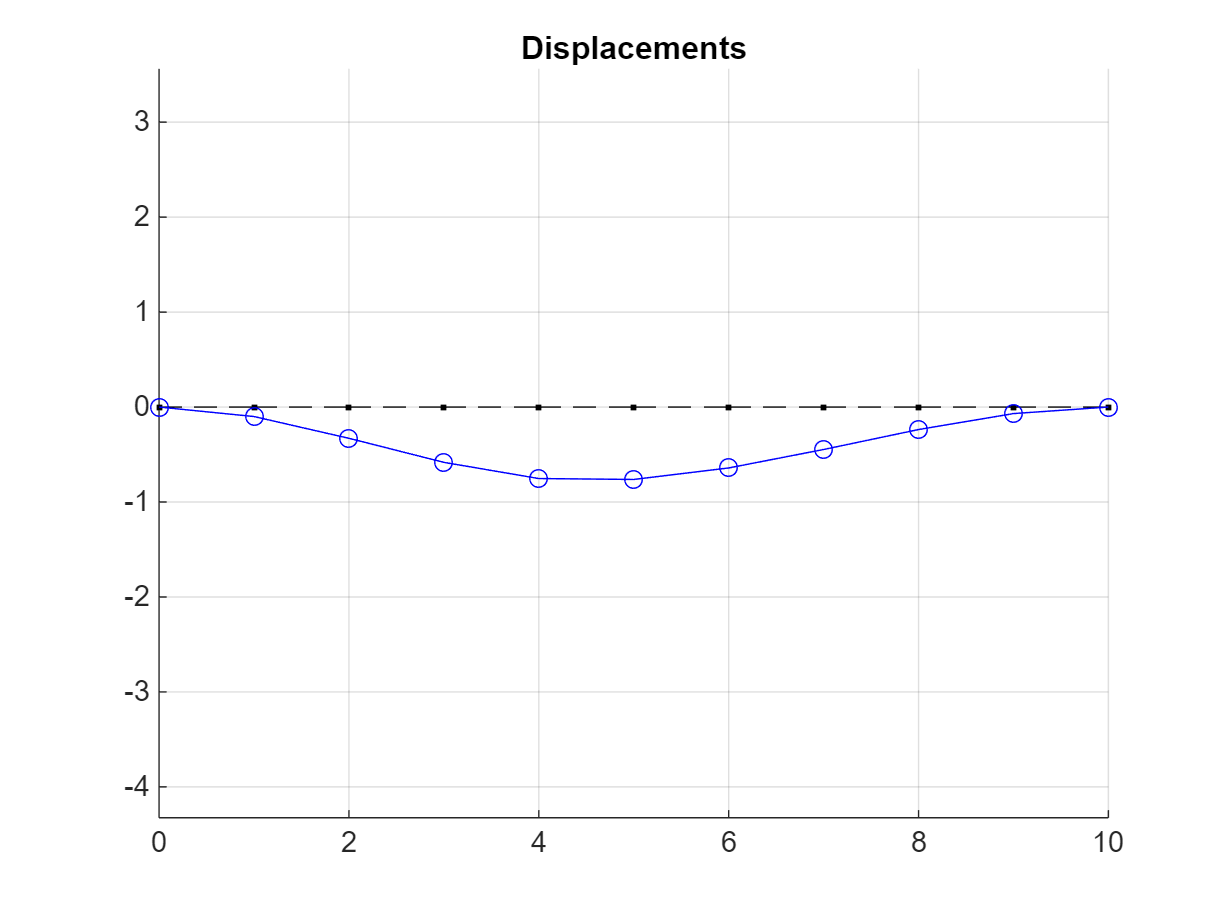


%----- Section forces -------------------------------------------

Ed = extract_ed(Edof,a);

[es1,edi1] = beam2s([0 1],[0 0],ep,Ed(1,:));
[es2,edi2] = beam2s([1 2],[0 0],ep,Ed(2,:));
[es3,edi3] = beam2s([2 3],[0 0],ep,Ed(3,:));
[es4,edi4] = beam2s([3 4],[0 0],ep,Ed(4,:));
[es5,edi5] = beam2s([4 5],[0 0],ep,Ed(5,:));
[es6,edi6] = beam2s([5 6],[0 0],ep,Ed(6,:));
[es7,edi7] = beam2s([6 7],[0 0],ep,Ed(7,:));
[es8,edi8] = beam2s([7 8],[0 0],ep,Ed(8,:));
[es9,edi9] = beam2s([8 9],[0 0],ep,Ed(9,:));
[es0,edi10] = beam2s([9 10],[0 0],ep,Ed(10,:));

%----- Draw deformed frame ---------------------------------------

figure
plotpar=[2 1 0];
eldraw2([0 1],[0 0],plotpar);
eldraw2([1 2],[0 0],plotpar);
eldraw2([2 3],[0 0],plotpar);
eldraw2([3 4],[0 0],plotpar);
eldraw2([4 5],[0 0],plotpar);
eldraw2([5 6],[0 0],plotpar);
eldraw2([6 7],[0 0],plotpar);
eldraw2([7 8],[0 0],plotpar);
eldraw2([8 9],[0 0],plotpar);
eldraw2([9 10],[0 0],plotpar);
 
sfac=scalfact2([0 1],[0 0],edi1,0.1);
plotpar=[1 2 1];

dispbeam2([0 1],[0 0],edi1,plotpar,sfac);
dispbeam2([1 2],[0 0],edi2,plotpar,sfac);
dispbeam2([2 3],[0 0],edi3,plotpar,sfac);
dispbeam2([3 4],[0 0],edi4,plotpar,sfac);
dispbeam2([4 5],[0 0],edi5,plotpar,sfac);
dispbeam2([5 6],[0 0],edi6,plotpar,sfac);
dispbeam2([6 7],[0 0],edi7,plotpar,sfac);
dispbeam2([7 8],[0 0],edi8,plotpar,sfac);
dispbeam2([8 9],[0 0],edi9,plotpar,sfac);
dispbeam2([9 10],[0 0],edi10,plotpar,sfac);
title('Displacements')
grid on

## Task 4

clear
% ------ Define Topology matrix
% Edof = [ele1, dof1, dof2
% ele2, dof1, dof2
% ..., ..., ...]
% ele. number, x ,y ,rotx , x+1 y+1 rotx+1
Edof = [1 1 2 5 6
        2 5 6 7 8
        3 3 4 5 6];

k = 1250; % N/m
F = -80e3 % N

F = -80000


E = 210e9; % GPa  
L = 10; % m

A1 = 0.0006; % m^2
A2 = 0.0003; 
A3 = 0.0010;

I = 2510e-8; % m^4

% ------ Initiate stiffness matrix K and load vector f
K = zeros(8);
f = zeros(8, 1);
f(6) = F;

%----- Element properties
E=2.0e11;
ep1=[E A1];    
ep2=[E A2];    
ep3=[E A3];	

%----- Element coordinates
ex1=[0 1.6];    
ex2=[1.6 1.6];    
ex3=[0 1.6];   
ey1=[0 0];      

ey2=[0 1.2];      
ey3=[1.2 0];  

%----- Element stiffness matrices
Ke1=bar2e(ex1,ey1,ep1)	 

Ke1 = 1.0e+07 *

    7.5000         0   -7.5000         0
         0         0         0         0
   -7.5000         0    7.5000         0
         0         0         0         0


Ke2=bar2e(ex2,ey2,ep2)

Ke2 = 1.0e+07 *

         0         0         0         0
         0    5.0000         0   -5.0000
         0         0         0         0
         0   -5.0000         0    5.0000


Ke3=bar2e(ex3,ey3,ep3)	

Ke3 =     64000000   -48000000   -64000000    48000000
   -48000000    36000000    48000000   -36000000
   -64000000    48000000    64000000   -48000000
    48000000   -36000000   -48000000    36000000



 
%----- Assemble Ke into K

K=assem(Edof(1,:),K,Ke1);
K=assem(Edof(2,:),K,Ke2); 
K=assem(Edof(3,:),K,Ke3)	

K = 1.0e+08 *

    0.7500         0         0         0   -0.7500         0         0         0
         0         0         0         0         0         0         0         0
         0         0    0.6400   -0.4800   -0.6400    0.4800         0         0
         0         0   -0.4800    0.3600    0.4800   -0.3600         0         0
   -0.7500         0   -0.6400    0.4800    1.3900   -0.4800         0         0
         0         0    0.4800   -0.3600   -0.4800    0.8600         0   -0.5000
         0         0         0         0         0         0         0         0
         0         0         0         0         0   -0.5000         0    0.5000


 
%----- Solve the system of equations

 bc = [1 0
      2 0
      3 0
      4 0
      7 0
      8 0];   

[a,r] = solveq(K,f,bc)

a =          0
         0
         0
         0
   -0.0004
   -0.0012
         0
         0


r = 1.0e+04 *

    2.9845
         0
   -2.9845
    2.2383
         0
         0
         0
    5.7617


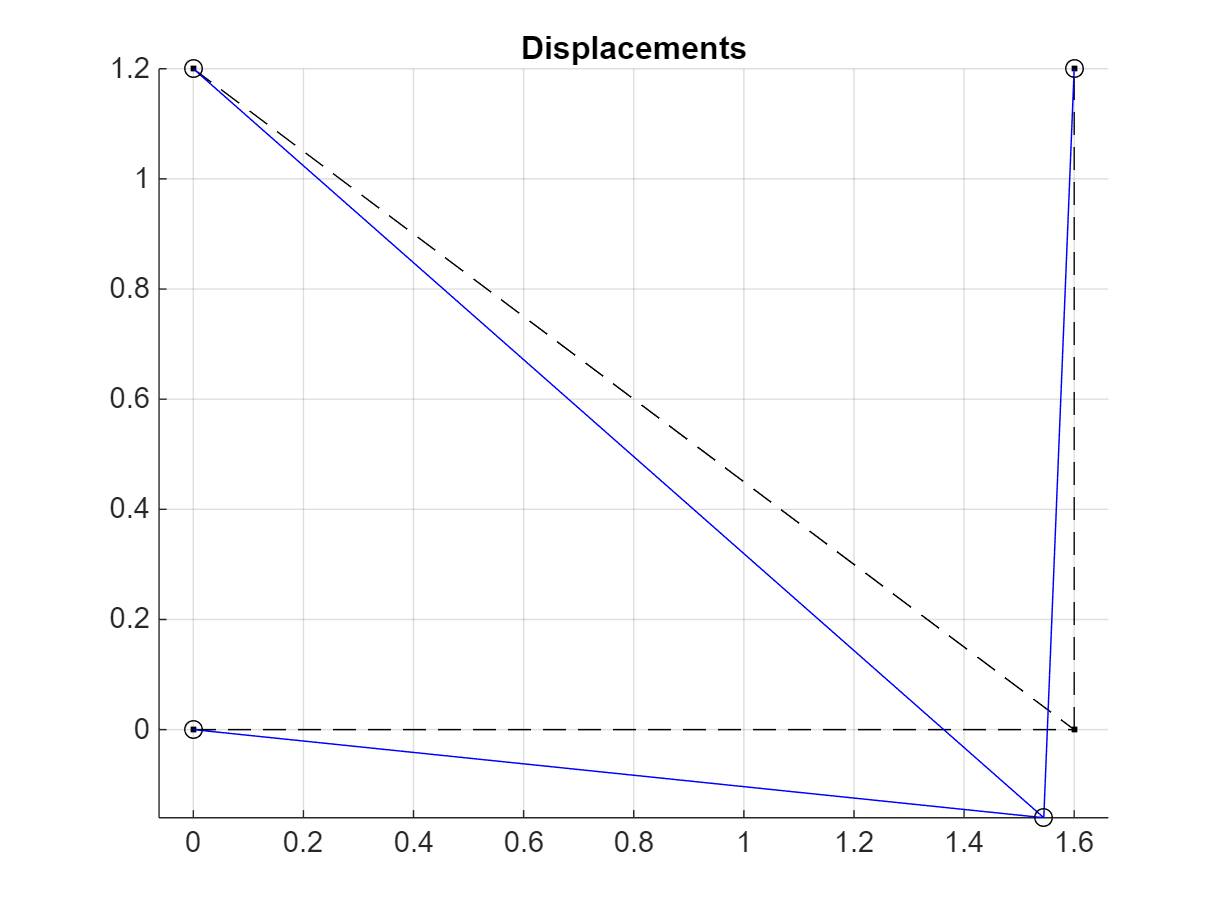


%----- Element forces

ed1=extract_ed(Edof(1,:),a);
ed2=extract_ed(Edof(2,:),a);
ed3=extract_ed(Edof(3,:),a);
 
%----- Draw deformed truss
 
figure
plotpar=[2 1 0];
eldraw2(ex1,ey1,plotpar);
eldraw2(ex2,ey2,plotpar);
eldraw2(ex3,ey3,plotpar);

sfac=scalfact2(ex1,ey1,ed1,0.1);
plotpar=[1 2 1];

eldisp2(ex1,ey1,ed1,plotpar,sfac);
eldisp2(ex2,ey2,ed2,plotpar,sfac);
eldisp2(ex3,ey3,ed3,plotpar,sfac);
title('Displacements')
grid on

## Task 5

clear
% ------ Define Topology matrix
% Edof = [ele1, dof1, dof2
% ele2, dof1, dof2
% ..., ..., ...]
% ele. number, x ,y ,rotx , x+1 y+1 rotx+1
Edof = [1 1 2 3 4
        2 3 4 5 6
        3 5 6 7 8
        4 7 8 9 10
        5 9 10 11 12
        6 11 12 13 14
        7 13 14 15 16
        8 1 2 13 14
        9 15 16 3 4
        10 3 4 11 12
        11 13 14 5 6
        12 5 6 9 10
        13 11 12 7 8
        14 13 14 17 18
        15 11 12 17 18
        16 3 4 13 14
        17 5 6 11 12];

k = 1250; % N/m
F = -0.5e6  % N

F = -500000


E = 210e9; % GPa  

A = 0.0025; % m^2

% I = 2510e-8; % m^4

% ------ Initiate stiffness matrix K and load vector f
K = zeros(18);
f = zeros(18, 1);
f(8) = F*cos(deg2rad(30));
f(7) = F*sin(deg2rad(30));

%----- Element properties
ep=[E A];    

%----- Element coordinates
ex1=[0 2];    
ey1=[0 0];

ex2=[2 4];    
ey2=[0 0];

ex3=[4 6];   
ey3=[0 0]; 

ex4=[6 6];    
ey4=[0 2];

ex5=[6 4];    
ey5=[2 2];   

ex6=[4 2];    
ey6=[2 2];   

ex7=[2 0];    
ey7=[2 2];   

ex8=[0 2];    
ey8=[0 2];   

ex9=[0 2];    
ey9=[2 0];   

ex10=[2 4];    
ey10=[0 2];   

ex11=[2 4];    
ey11=[2 0];   

ex12=[4 6];    
ey12=[0 2];   

ex13=[4 6];    
ey13=[2 0];   

ex14=[2 3];    
ey14=[2 3];   

ex15=[4 3];    
ey15=[2 3]; 

ex16=[2 2];    
ey16=[0 2]; 

ex17=[4 4];    
ey17=[0 2]; 

%----- Element stiffness matrices
Ke1=bar2e(ex1,ey1,ep)	 

Ke1 =    262500000           0  -262500000           0
           0           0           0           0
  -262500000           0   262500000           0
           0           0           0           0


Ke2=bar2e(ex2,ey2,ep)

Ke2 =    262500000           0  -262500000           0
           0           0           0           0
  -262500000           0   262500000           0
           0           0           0           0


Ke3=bar2e(ex3,ey3,ep)

Ke3 =    262500000           0  -262500000           0
           0           0           0           0
  -262500000           0   262500000           0
           0           0           0           0


Ke4=bar2e(ex4,ey4,ep)

Ke4 =            0           0           0           0
           0   262500000           0  -262500000
           0           0           0           0
           0  -262500000           0   262500000


Ke5=bar2e(ex5,ey5,ep)

Ke5 =    262500000           0  -262500000           0
           0           0           0           0
  -262500000           0   262500000           0
           0           0           0           0


Ke6=bar2e(ex6,ey6,ep)

Ke6 =    262500000           0  -262500000           0
           0           0           0           0
  -262500000           0   262500000           0
           0           0           0           0


Ke7=bar2e(ex7,ey7,ep)

Ke7 =    262500000           0  -262500000           0
           0           0           0           0
  -262500000           0   262500000           0
           0           0           0           0


Ke8=bar2e(ex8,ey8,ep)

Ke8 = 1.0e+07 *

    9.2808    9.2808   -9.2808   -9.2808
    9.2808    9.2808   -9.2808   -9.2808
   -9.2808   -9.2808    9.2808    9.2808
   -9.2808   -9.2808    9.2808    9.2808


Ke9=bar2e(ex9,ey9,ep)

Ke9 = 1.0e+07 *

    9.2808   -9.2808   -9.2808    9.2808
   -9.2808    9.2808    9.2808   -9.2808
   -9.2808    9.2808    9.2808   -9.2808
    9.2808   -9.2808   -9.2808    9.2808


Ke10=bar2e(ex10,ey10,ep)

Ke10 = 1.0e+07 *

    9.2808    9.2808   -9.2808   -9.2808
    9.2808    9.2808   -9.2808   -9.2808
   -9.2808   -9.2808    9.2808    9.2808
   -9.2808   -9.2808    9.2808    9.2808


Ke11=bar2e(ex11,ey11,ep)

Ke11 = 1.0e+07 *

    9.2808   -9.2808   -9.2808    9.2808
   -9.2808    9.2808    9.2808   -9.2808
   -9.2808    9.2808    9.2808   -9.2808
    9.2808   -9.2808   -9.2808    9.2808


Ke12=bar2e(ex12,ey12,ep)

Ke12 = 1.0e+07 *

    9.2808    9.2808   -9.2808   -9.2808
    9.2808    9.2808   -9.2808   -9.2808
   -9.2808   -9.2808    9.2808    9.2808
   -9.2808   -9.2808    9.2808    9.2808


Ke13=bar2e(ex13,ey13,ep)

Ke13 = 1.0e+07 *

    9.2808   -9.2808   -9.2808    9.2808
   -9.2808    9.2808    9.2808   -9.2808
   -9.2808    9.2808    9.2808   -9.2808
    9.2808   -9.2808   -9.2808    9.2808


Ke14=bar2e(ex14,ey14,ep)

Ke14 = 1.0e+08 *

    1.8562    1.8562   -1.8562   -1.8562
    1.8562    1.8562   -1.8562   -1.8562
   -1.8562   -1.8562    1.8562    1.8562
   -1.8562   -1.8562    1.8562    1.8562


Ke15=bar2e(ex15,ey15,ep)

Ke15 = 1.0e+08 *

    1.8562   -1.8562   -1.8562    1.8562
   -1.8562    1.8562    1.8562   -1.8562
   -1.8562    1.8562    1.8562   -1.8562
    1.8562   -1.8562   -1.8562    1.8562


Ke16=bar2e(ex16,ey16,ep)

Ke16 =            0           0           0           0
           0   262500000           0  -262500000
           0           0           0           0
           0  -262500000           0   262500000


Ke17=bar2e(ex17,ey17,ep)

Ke17 =            0           0           0           0
           0   262500000           0  -262500000
           0           0           0           0
           0  -262500000           0   262500000


 
%----- Assemble Ke into K

K=assem(Edof(1,:),K,Ke1);
K=assem(Edof(2,:),K,Ke2); 
K=assem(Edof(3,:),K,Ke3);
K=assem(Edof(4,:),K,Ke4);
K=assem(Edof(5,:),K,Ke5);
K=assem(Edof(6,:),K,Ke6);
K=assem(Edof(7,:),K,Ke7);
K=assem(Edof(8,:),K,Ke8);
K=assem(Edof(9,:),K,Ke9);
K=assem(Edof(10,:),K,Ke10);
K=assem(Edof(11,:),K,Ke11);
K=assem(Edof(12,:),K,Ke12);
K=assem(Edof(13,:),K,Ke13);
K=assem(Edof(14,:),K,Ke14);
K=assem(Edof(15,:),K,Ke15);
K=assem(Edof(16,:),K,Ke16);
K=assem(Edof(17,:),K,Ke17);

%----- Solve the system of equations

 bc = [1 0
      2 0
      15 0
      16 0];   

[a,r] = solveq(K,f,bc)

a =          0
         0
   -0.0050
   -0.0070
   -0.0083
   -0.0215
   -0.0101
   -0.0406
    0.0076
   -0.0397


r = 1.0e+06 *

    1.5490
    0.2427
   -0.0000
         0
   -0.0000
    0.0000
    0.0000
    0.0000
   -0.0000
    0.0000


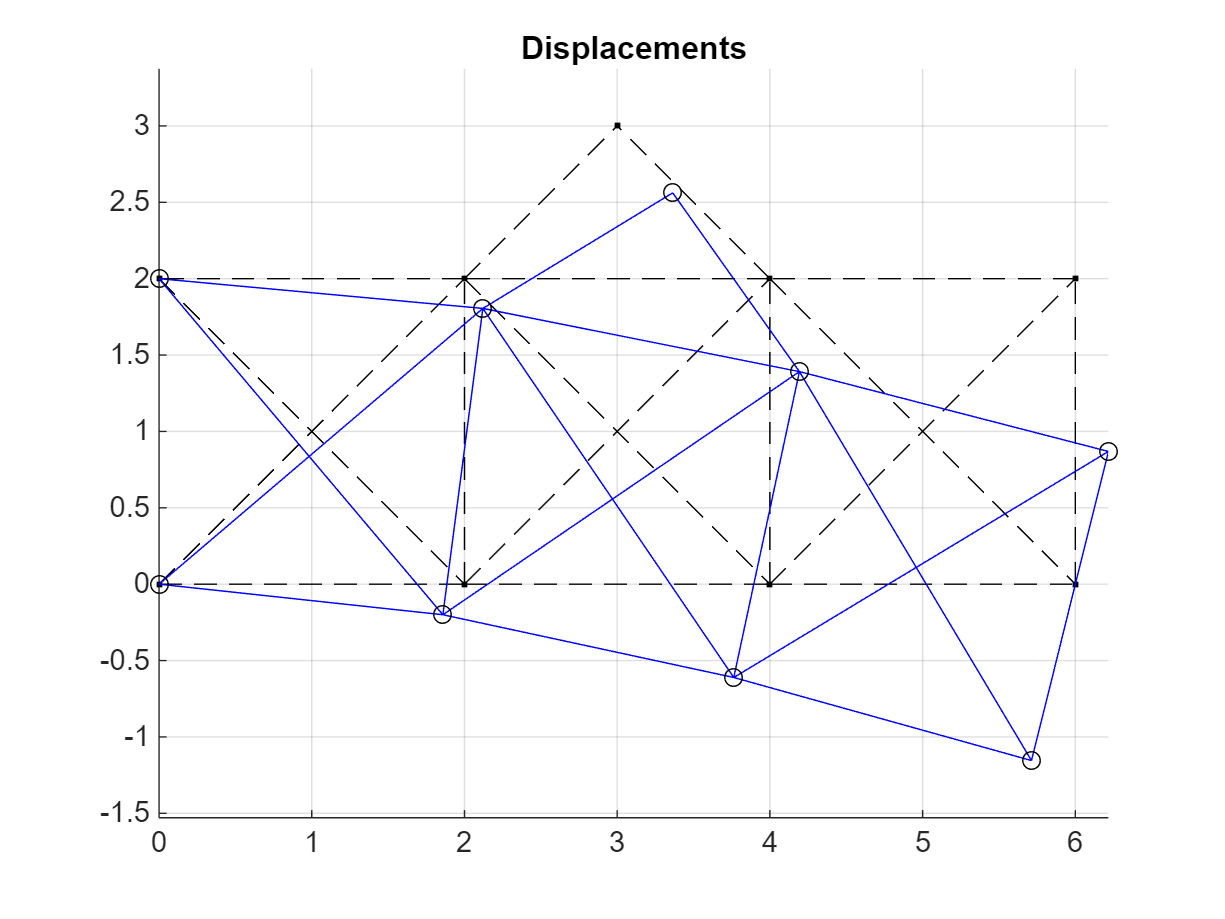


%----- Element forces

ed1=extract_ed(Edof(1,:),a);
ed2=extract_ed(Edof(2,:),a);
ed3=extract_ed(Edof(3,:),a);
ed4=extract_ed(Edof(4,:),a);
ed5=extract_ed(Edof(5,:),a);
ed6=extract_ed(Edof(6,:),a);
ed7=extract_ed(Edof(7,:),a);
ed8=extract_ed(Edof(8,:),a);
ed9=extract_ed(Edof(9,:),a);
ed10=extract_ed(Edof(10,:),a);
ed11=extract_ed(Edof(11,:),a);
ed12=extract_ed(Edof(12,:),a);
ed13=extract_ed(Edof(13,:),a);
ed14=extract_ed(Edof(14,:),a);
ed15=extract_ed(Edof(15,:),a);
ed16=extract_ed(Edof(16,:),a);
ed17=extract_ed(Edof(17,:),a);

%----- Draw deformed truss
 
figure
plotpar=[2 1 0];
eldraw2(ex1,ey1,plotpar);
eldraw2(ex2,ey2,plotpar);
eldraw2(ex3,ey3,plotpar);
eldraw2(ex4,ey4,plotpar);
eldraw2(ex5,ey5,plotpar);
eldraw2(ex6,ey6,plotpar);
eldraw2(ex7,ey7,plotpar);
eldraw2(ex8,ey8,plotpar);
eldraw2(ex9,ey9,plotpar);
eldraw2(ex10,ey10,plotpar);
eldraw2(ex11,ey11,plotpar);
eldraw2(ex12,ey12,plotpar);
eldraw2(ex13,ey13,plotpar);
eldraw2(ex14,ey14,plotpar);
eldraw2(ex15,ey15,plotpar);
eldraw2(ex16,ey16,plotpar);
eldraw2(ex17,ey17,plotpar);

sfac=scalfact2(ex1,ey1,ed1,0.1);
plotpar=[1 2 1];

eldisp2(ex1,ey1,ed1,plotpar,sfac);
eldisp2(ex2,ey2,ed2,plotpar,sfac);
eldisp2(ex3,ey3,ed3,plotpar,sfac);
eldisp2(ex4,ey4,ed4,plotpar,sfac);
eldisp2(ex5,ey5,ed5,plotpar,sfac);
eldisp2(ex6,ey6,ed6,plotpar,sfac);
eldisp2(ex7,ey7,ed7,plotpar,sfac);
eldisp2(ex8,ey8,ed8,plotpar,sfac);
eldisp2(ex9,ey9,ed9,plotpar,sfac);
eldisp2(ex10,ey10,ed10,plotpar,sfac);
eldisp2(ex11,ey11,ed11,plotpar,sfac);
eldisp2(ex12,ey12,ed12,plotpar,sfac);
eldisp2(ex13,ey13,ed13,plotpar,sfac);
eldisp2(ex14,ey14,ed14,plotpar,sfac);
eldisp2(ex15,ey15,ed15,plotpar,sfac);
eldisp2(ex16,ey16,ed16,plotpar,sfac);
eldisp2(ex17,ey17,ed17,plotpar,sfac);
title('Displacements')
grid on